%linear convolution
% all three methods
% 1.using ifft(fft(x,l).*fft(h,l))
%2. using for loop
% using function conv(x,h)
clc
clear all
close all
x=input('enter x: ')

x =      1     2     3     4


h=input('enter h: ')

h =      2     1     2     1


N=length(x)

N = 4

M=length(h)

M = 4

l=N+M-1

l = 7

z=conv(x,h)

z =      2     5    10    16    12    11     4


lc=ifft(fft(x,l).*fft(h,l))

lc =     2.0000    5.0000   10.0000   16.0000   12.0000   11.0000    4.0000


y=zeros(1,l)

y =      0     0     0     0     0     0     0


for n=1:l
    for k=max(n-M+1,1):min(n,N)
        y(n)=y(n)+x(n-k+1)*h(k)
    end
end

y =      2     0     0     0     0     0     0


y =      2     4     0     0     0     0     0


y =      2     5     0     0     0     0     0


y =      2     5     6     0     0     0     0


y =      2     5     8     0     0     0     0


y =      2     5    10     0     0     0     0


y =      2     5    10     8     0     0     0


y =      2     5    10    11     0     0     0


y =      2     5    10    15     0     0     0


y =      2     5    10    16     0     0     0


y =      2     5    10    16     4     0     0


y =      2     5    10    16    10     0     0


y =      2     5    10    16    12     0     0


y =      2     5    10    16    12     8     0


y =      2     5    10    16    12    11     0


y =      2     5    10    16    12    11     4



% algorithm
%1. give input x,y
% find l=N+M-1 N=length(x) and M=length(h)
% assign y with alll zeros of length l
% 2. compute linear conv using conv fun 
% compute linear conv by applying ifft on product of fft's of x and h
% 3. compute lc by using for loop
% 4.verify all

% same flow chart


%circular conv using function cconv(x,h,l), 
% l=max(h,x lengths)
% cc=ifft(fft(x).*fft(h))
clc
clear all
close all
x=input('enter x')

x =      1     2     3     4


h=input('enter h')

h =      2     1     2     1


l=max(length(x),length(h))

l = 4

y=zeros(1,l)

y =      0     0     0     0


for n=1:l
    for k=1:l
        id=mod(n-k,l)+1
        y(n)=y(n)+x(id)*h(k)
    end
end

id = 1

y =      2     0     0     0


id = 4

y =      6     0     0     0


id = 3

y =     12     0     0     0


id = 2

y =     14     0     0     0


id = 2

y =     14     4     0     0


id = 1

y =     14     5     0     0


id = 4

y =     14    13     0     0


id = 3

y =     14    16     0     0


id = 3

y =     14    16     6     0


id = 2

y =     14    16     8     0


id = 1

y =     14    16    10     0


id = 4

y =     14    16    14     0


id = 4

y =     14    16    14     8


id = 3

y =     14    16    14    11


id = 2

y =     14    16    14    15


id = 1

y =     14    16    14    16


z=cconv(x,h,l)

z =     14    16    14    16


cc=ifft(fft(x).*fft(h))

cc =     14    16    14    16



%algorithm and flow chart


%dft
clc
clear all
close all
x=input('enter x ')

x =      1     2     3     4


N=length(x)

N = 4

y=zeros(1,N)

y =      0     0     0     0


for n=0:N-1
    for k=0:N-1
        y(n+1)=y(n+1)+x(k+1)*exp(-1*1i*2*pi*n*k/N)
    end
end

y =      1     0     0     0


y =      3     0     0     0


y =      6     0     0     0


y =     10     0     0     0


y =     10     1     0     0


y =   10.0000 + 0.0000i   1.0000 - 2.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


y =   10.0000 + 0.0000i  -2.0000 - 2.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


y =   10.0000 + 0.0000i  -2.0000 + 2.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


y =   10.0000 + 0.0000i  -2.0000 + 2.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i


y =   10.0000 + 0.0000i  -2.0000 + 2.0000i  -1.0000 - 0.0000i   0.0000 + 0.0000i


y =   10.0000 + 0.0000i  -2.0000 + 2.0000i   2.0000 + 0.0000i   0.0000 + 0.0000i


y =   10.0000 + 0.0000i  -2.0000 + 2.0000i  -2.0000 - 0.0000i   0.0000 + 0.0000i


y =   10.0000 + 0.0000i  -2.0000 + 2.0000i  -2.0000 - 0.0000i   1.0000 + 0.0000i


y =   10.0000 + 0.0000i  -2.0000 + 2.0000i  -2.0000 - 0.0000i   1.0000 + 2.0000i


y =   10.0000 + 0.0000i  -2.0000 + 2.0000i  -2.0000 - 0.0000i  -2.0000 + 2.0000i


y =   10.0000 + 0.0000i  -2.0000 + 2.0000i  -2.0000 - 0.0000i  -2.0000 - 2.0000i


z=fft(x)

z =   10.0000 + 0.0000i  -2.0000 + 2.0000i  -2.0000 + 0.0000i  -2.0000 - 2.0000i


%idft
clc
clear all
close all
x=input('enter x: ')

x =      1     2     3     4


N=length(x)

N = 4

y=zeros(1,N)

y =      0     0     0     0


for n=0:N-1
    for k=0:N-1
        y(n+1)=y(n+1)+x(k+1)*exp(1i*2*pi*n*k/N)
    end
    y(n+1)=y(n+1)/N
end

y =      1     0     0     0


y =      3     0     0     0


y =      6     0     0     0


y =     10     0     0     0


y =     2.5000         0         0         0


y =     2.5000    1.0000         0         0


y =    2.5000 + 0.0000i   1.0000 + 2.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


y =    2.5000 + 0.0000i  -2.0000 + 2.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


y =    2.5000 + 0.0000i  -2.0000 - 2.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


y =    2.5000 + 0.0000i  -0.5000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i


y =    2.5000 + 0.0000i  -0.5000 - 0.5000i   1.0000 + 0.0000i   0.0000 + 0.0000i


y =    2.5000 + 0.0000i  -0.5000 - 0.5000i  -1.0000 + 0.0000i   0.0000 + 0.0000i


y =    2.5000 + 0.0000i  -0.5000 - 0.5000i   2.0000 - 0.0000i   0.0000 + 0.0000i


y =    2.5000 + 0.0000i  -0.5000 - 0.5000i  -2.0000 + 0.0000i   0.0000 + 0.0000i


y =    2.5000 + 0.0000i  -0.5000 - 0.5000i  -0.5000 + 0.0000i   0.0000 + 0.0000i


y =    2.5000 + 0.0000i  -0.5000 - 0.5000i  -0.5000 + 0.0000i   1.0000 + 0.0000i


y =    2.5000 + 0.0000i  -0.5000 - 0.5000i  -0.5000 + 0.0000i   1.0000 - 2.0000i


y =    2.5000 + 0.0000i  -0.5000 - 0.5000i  -0.5000 + 0.0000i  -2.0000 - 2.0000i


y =    2.5000 + 0.0000i  -0.5000 - 0.5000i  -0.5000 + 0.0000i  -2.0000 + 2.0000i


y =    2.5000 + 0.0000i  -0.5000 - 0.5000i  -0.5000 + 0.0000i  -0.5000 + 0.5000i


z=ifft(x)

z =    2.5000 + 0.0000i  -0.5000 - 0.5000i  -0.5000 + 0.0000i  -0.5000 + 0.5000i


% power spectral density two-sided
clc
clear all
close all
fs=10000

fs = 10000

f1=500

f1 = 500

f2=2000

f2 = 2000

N=200

N = 200

t=0:N-1

t =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


sgnl=sin(2*pi*f1*t/fs)+2*sin(2*pi*f2*t/fs)

sgnl =          0    2.2111    1.7634   -0.3666   -0.9511    1.0000    2.8532    1.9846   -0.5878   -1.5931   -0.0000    1.5931    0.5878   -1.9846   -2.8532   -1.0000    0.9511    0.3666   -1.7634   -2.2111   -0.0000    2.2111    1.7634   -0.3666   -0.9511    1.0000    2.8532    1.9846   -0.5878   -1.5931   -0.0000    1.5931    0.5878   -1.9846   -2.8532   -1.0000    0.9511    0.3666   -1.7634   -2.2111   -0.0000    2.2111    1.7634   -0.3666   -0.9511    1.0000    2.8532    1.9846   -0.5878   -1.5931


xf=abs(fft(sgnl))/N

xf =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.5000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


power_two=xf.*xf

power_two =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.2500    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


f=(0:N-1)*fs/N

f =            0          50         100         150         200         250         300         350         400         450         500         550         600         650         700         750         800         850         900         950        1000        1050        1100        1150        1200        1250        1300        1350        1400        1450        1500        1550        1600        1650        1700        1750        1800        1850        1900        1950        2000        2050        2100        2150        2200        2250        2300        2350        2400        2450


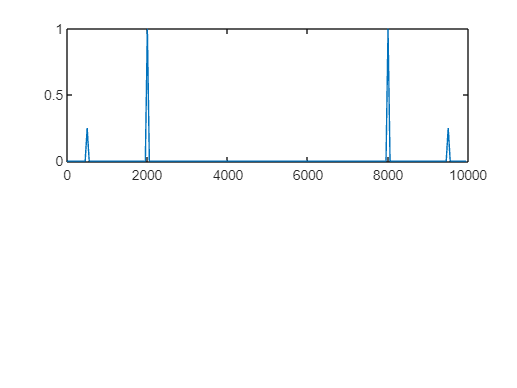

subplot(2,1,1)
plot(f,power_two)

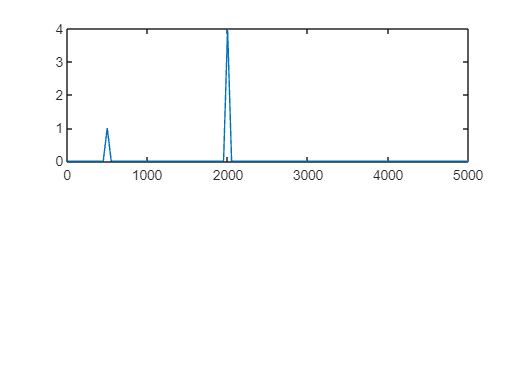

clc
clear all
close all
fs = 10000;
f1 = 500;
f2 = 2000;
N = 200;
t = 0:N-1;
sgnl = sin(2*pi*f1*t/fs) + 2*sin(2*pi*f2*t/fs);
xf = abs(fft(sgnl))/N;
u = 2*xf;
xf(1) = xf(1)/2;
power_one = u .* u;
f = (0:(N-1)/2+1) * fs/N;
subplot(2,1,1)
plot(f,power_one(1:N/2+1))

clc
clear all
close all
fs=10000

fs = 10000

f1=500

f1 = 500

f2=2000

f2 = 2000

N=200

N = 200

t=0:N-1

t =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


x=sin(2*pi*f1*t/fs)+2*sin(2*pi*f2*t/fs)

x =          0    2.2111    1.7634   -0.3666   -0.9511    1.0000    2.8532    1.9846   -0.5878   -1.5931   -0.0000    1.5931    0.5878   -1.9846   -2.8532   -1.0000    0.9511    0.3666   -1.7634   -2.2111   -0.0000    2.2111    1.7634   -0.3666   -0.9511    1.0000    2.8532    1.9846   -0.5878   -1.5931   -0.0000    1.5931    0.5878   -1.9846   -2.8532   -1.0000    0.9511    0.3666   -1.7634   -2.2111   -0.0000    2.2111    1.7634   -0.3666   -0.9511    1.0000    2.8532    1.9846   -0.5878   -1.5931


xf=abs(fft(x))/N

xf =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.5000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


pow_two=xf.*xf

pow_two =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.2500    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


f=(0:N-1)*fs/N

f =            0          50         100         150         200         250         300         350         400         450         500         550         600         650         700         750         800         850         900         950        1000        1050        1100        1150        1200        1250        1300        1350        1400        1450        1500        1550        1600        1650        1700        1750        1800        1850        1900        1950        2000        2050        2100        2150        2200        2250        2300        2350        2400        2450


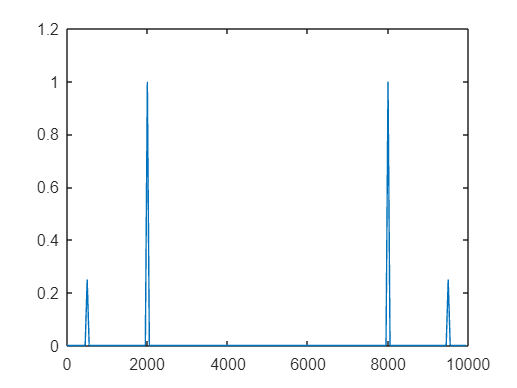

plot(f,pow_two)

clc
clear all
close all
fs=10000

fs = 10000

f1=500

f1 = 500

f2=2000

f2 = 2000

N=200

N = 200

t=0:N-1

t =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


x=sin(2*pi*f1*t/fs)+2*sin(2*pi*f2*t/fs)

x =          0    2.2111    1.7634   -0.3666   -0.9511    1.0000    2.8532    1.9846   -0.5878   -1.5931   -0.0000    1.5931    0.5878   -1.9846   -2.8532   -1.0000    0.9511    0.3666   -1.7634   -2.2111   -0.0000    2.2111    1.7634   -0.3666   -0.9511    1.0000    2.8532    1.9846   -0.5878   -1.5931   -0.0000    1.5931    0.5878   -1.9846   -2.8532   -1.0000    0.9511    0.3666   -1.7634   -2.2111   -0.0000    2.2111    1.7634   -0.3666   -0.9511    1.0000    2.8532    1.9846   -0.5878   -1.5931


xf=abs(fft(x))/N

xf =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.5000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


u=2*xf

u =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    2.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


xf(1)=xf(1)/2

xf =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.5000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


one_pow=u.*u 

one_pow =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    4.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


f=(0:(N-1)/2+1)*fs/N

f =            0          50         100         150         200         250         300         350         400         450         500         550         600         650         700         750         800         850         900         950        1000        1050        1100        1150        1200        1250        1300        1350        1400        1450        1500        1550        1600        1650        1700        1750        1800        1850        1900        1950        2000        2050        2100        2150        2200        2250        2300        2350        2400        2450


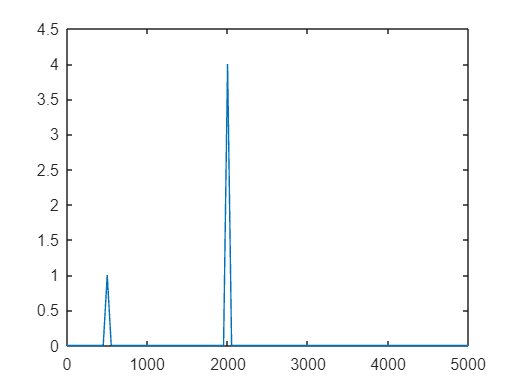

plot(f,one_pow(1:N/2+1))